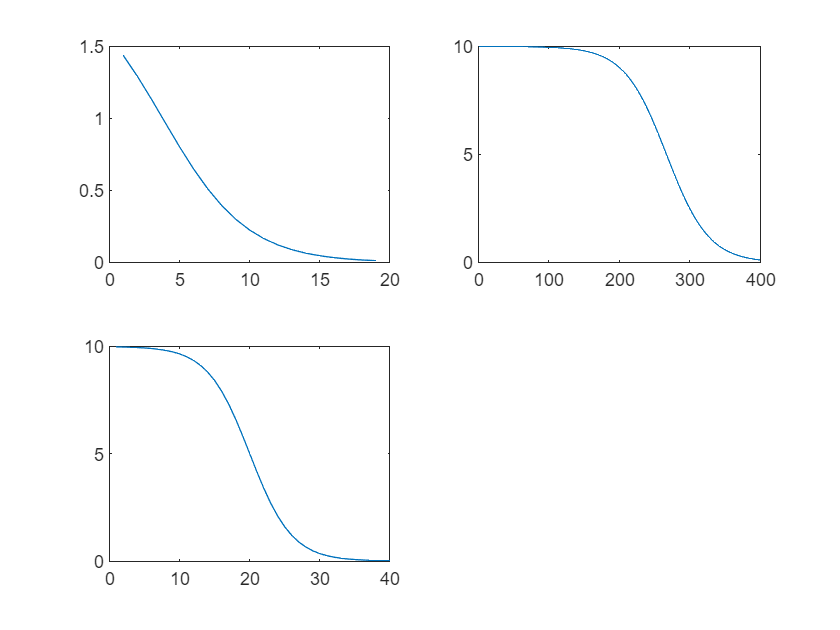



cd C:\Users\mikol\Desktop\signals\dworakowski\lab1\functions;
n=5;
[best,meanms,stdms,Results,Step]=multistartF(n);
[best1,meanms1,stdms1,Results1,Step1]=multistartM(n);
[best2,meanms2,stdms2,Results2,Step2]=jpjvsf(n);
[best3,meanms3,stdms3,Results3,Step3]=jpjvsm(n);
cd C:\Users\mikol\Desktop\signals\dworakowski\lab2\functions;
[best4,~,meanGAesVar,stdGAesVar,BestHistory,CurrentHistory,Step4]...
    = GAesVarF(n,40,20,19,10,2,3);
[bestresult,Results,meanGAesVar,stdGAesVar,BestHistory,CurrentHistory,Step5] = ...
    GAesVarM(n,38,21,19,15,2,3);


bestresults=[best,best2,best4];

%T=table()
% disp('for multistart fewminima: mean ');disp(meanms);disp(' std ');disp(stdms);disp(' best result ');disp(best);disp(' for multistart manyminima: mean ');disp(meanms1);disp(' std ');
% disp(stdms1);disp(' best result ');disp(best1);disp(' for 1+1 few...: mean ');disp(meanms2);disp(' std ');disp(stdms2);disp(' best result ');disp(best2);
% disp(' for 1+1 many...: mean ');disp(meanms3);disp(' std ');disp(stdms3);disp(' best result ');disp('');disp('');disp('');disp('');
% disp('');disp('');disp('');disp('');disp('');disp('');disp('');disp('');disp('');

figure(1);
subplot(2,2,1);
plot(Step);
subplot(2,2,2);
plot(Step2);
subplot(2,2,3);
plot(Step4);

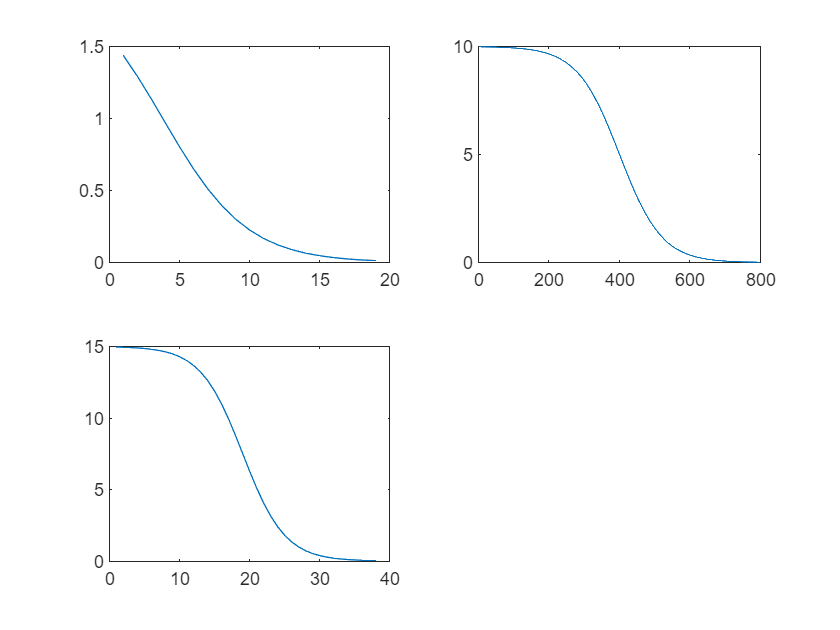


figure(2);
subplot(2,2,1);
plot(Step1);
subplot(2,2,2);
plot(Step3);
subplot(2,2,3);
plot(Step5);

figure(3);

